## * CALISTA MAIN SCRIPT *

Example 9.Analysis of peripherical blood mononuclear cells (PBMCs) (`Example_9_ZHENG_scDrop_seq.m` script in the main folder of CALISTA)

Analysis of Drop-seq data of Zheng et al. ([Zheng, G. X. Y. et al. Massively parallel digital transcriptional profiling of single cells. Nat. Commun. 8, 14049 (2017).](https://www.nature.com/articles/ncomms14049)).

We begin with changing the current directory in MATLAB to the CALISTA folder. Type '`cd`' in the command window then copy and paste the current path in '`curr_path`':

clc
clear all
close all

% Add path for CALISTA folder:
% mfilename=matlab.desktop.editor.getActiveFilename;
% curr_path=fileparts(which(mfilename));

% In windows
% curr_path='C:\Users\npgao\polybox\AAA ETH project CALISTA\CALISTA-MATLAB 1.2 dropout\CALISTA-MATLAB 1.2.1';
% In MacOS
curr_path='/Users/nan/polybox/AAA ETH project CALISTA/CALISTA-MATLAB 1.2 dropout/CALISTA-MATLAB 1.2.1';

cd(curr_path);
addpath(genpath(curr_path))
warning ('off','all');

## * 1-Data Import and Preprocessing *

Type '`help import_data`' in the command window for more information 

Run the following section and import Zheng dataset (available in the subfolder *EXAMPLES/ZHENG*).



**** Please upload normalized data. File formats accepted: .txt , .xlxs , .csv, .mat, .loom ****


Filtering genes by number of cells...

Filtering cells by number of genes...

% of zeros in the data  96.83

Scaling the data...

Selecting most variable genes...


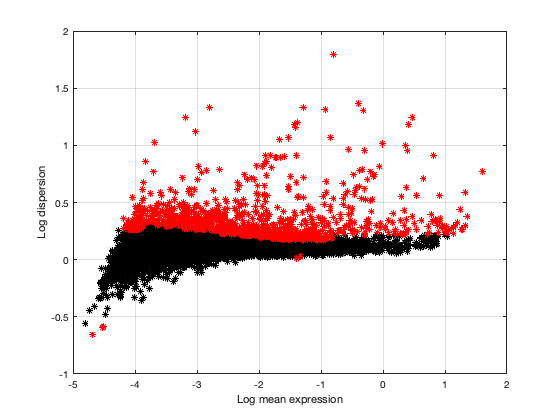


Normalizing the data...

Dropout estimation...


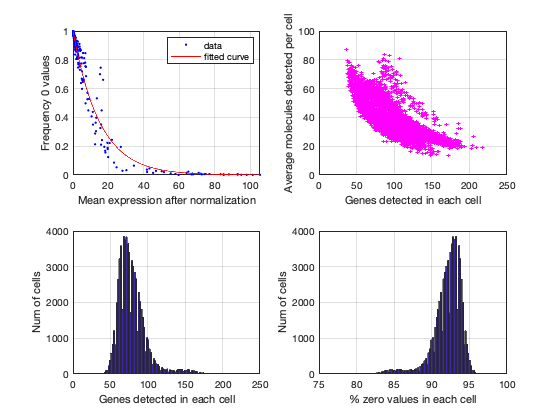


Top genes selection...


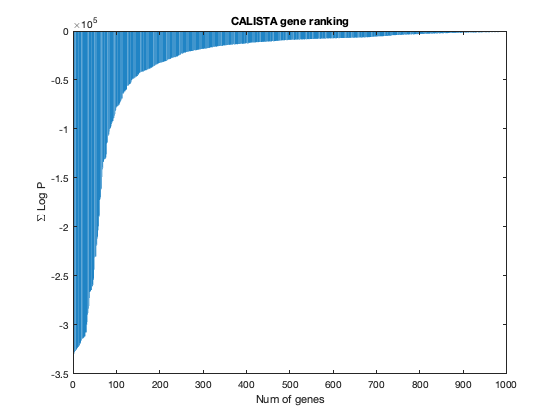


Finishing setup of the CALISTA data structure...

DONE.


%% *** 1-Data Import and Preprocessing ***
%
% Type 'help import_data' for more information 
%
% Specify pre-processing settings
INPUTS.data_type=5; % snRNA-seq data
INPUTS.format_data=6; % (RECOMMENDED FOR Droplet-based datasets) File .mat containing the following variables:
%                       'expMatrix': NxG expression matrix with rows=cells and columns=genes;
%                       'cellID': cell array/character vector containing cell IDs (not required)
%                       'geneNAMES': cell array containing gene names (not required)
%                       'timeline': 1xN numerical vector containing the time information (not required)
INPUTS.zeros_genes=3; % Remove genes with > 3 zero values
INPUTS.zeros_cells=200; % Remove cells with zero values>200
INPUTS.top_genes=200; % Retain only top 200 most variable genes
%
% Specify single-cell clustering settings
INPUTS.use_drop_prob_in_clustering=1;
INPUTS.optimize=0; % The number of cluster is known a priori

% Upload and pre-process data 
[DATA,INPUTS] = import_data(INPUTS);

CALISTA processes the data from each time point separately.

## * 2-SINGLE-CELL CLUSTERING *

Type '`help CALISTA_clustering_main`' in the command window for more information. 

Following the clustering analysis of the original publication, We set the number of clusters to **10**.


CALISTA_clustering is running...
Progress:
....................
||||||||||||||||||||

Best cell assignment...
Elapsed time is 260.471709 seconds.

No time info found. Please enter the starting cell or the marker gene whenever available



Skip relabelling step

Plotting...


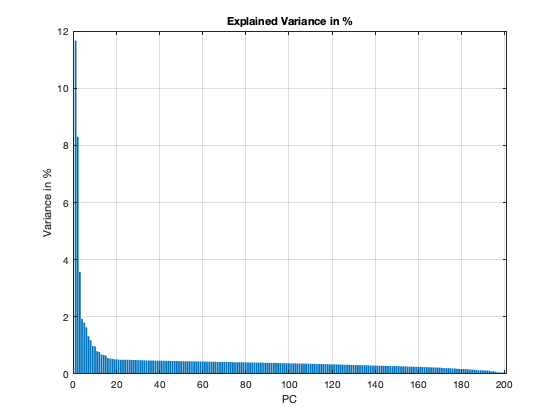

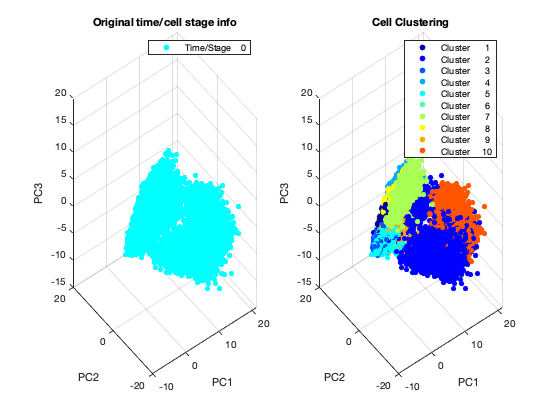

Elapsed time is 299.195804 seconds.

DONE.


[Results, DATA, INPUTS]=CALISTA_clustering_main(DATA,INPUTS);

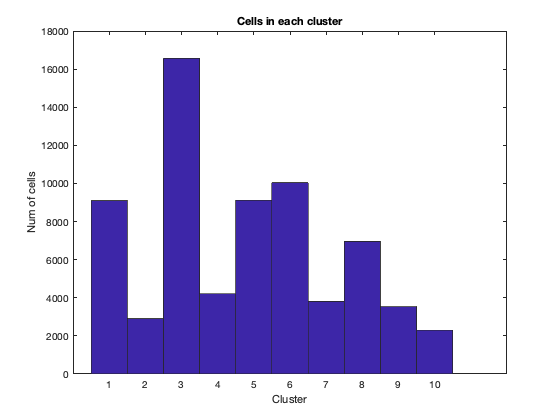

% cgo = clustergram(W_1','Colormap',redbluecmap,'Standardize','row','Linkage','average')
% Testing
figure
hist(Results.final_groups,1:Results.expected_clusters)
title('Cells in each cluster')
xlabel('Cluster')
ylabel('Num of cells')